# Image Compression with Sparse Vector Fields Regularisation

*Eva-Maria Brinkmann, Martin Burger, Joana Sarah Grah*

"Regularization with sparse vector fields: from image compression to TV-type reconstruction." *International Conference on Scale Space and Variational Methods in Computer Vision*. Springer, Cham, 2015.

This code performs image compression for a given image by using the SVF model optimised by a primal-dual algorithm.

## Load Trui test image

load Trui.mat
[m,n] = size(img);

## Set Parameters

lambda = 10;                                       %weighting parameter (data term)

Dy = spdiags([-ones(m,1) ones(m,1)], [0 1], m, m);
Dy(m,:) = 0;
Dx = spdiags([-ones(n,1) ones(n,1)], [0 1], n, n);
Dx(n,:) = 0;
DX = kron(Dx, speye(m));                           %gradient matrices
DY = kron(speye(n), Dy);
divX = -DX';                                       %divergence matrices
divY = -DY';
lap = divX*DX + divY*DY;                           %Laplace matrix
K = [lap -divX -divY];                             %operator K

algorithmParam.sigma = 1/sqrt(normest(K'*K));      %primal step size

algorithmParam.tau = algorithmParam.sigma;         %dual step size
algorithmParam.theta = 1;                          %primal-dual overrelaxation parameter
algorithmParam.maxIter = 10000;                    %maximum number of primal-dual iterations
algorithmParam.epsilon = 1e-3;                     %primal-dual residual threshold

## Optimisation

[u, v] = primaldualOptimisation_live(img, K, algorithmParam, lambda);

Iteration 250. Primal-Dual Residual: 0.0071087
Iteration 500. Primal-Dual Residual: 0.0048499
Iteration 750. Primal-Dual Residual: 0.0037438
Iteration 1000. Primal-Dual Residual: 0.0031321
Iteration 1250. Primal-Dual Residual: 0.0027307
Iteration 1500. Primal-Dual Residual: 0.0024391
Iteration 1750. Primal-Dual Residual: 0.0022214
Iteration 2000. Primal-Dual Residual: 0.0020497
Iteration 2250. Primal-Dual Residual: 0.0019104
Iteration 2500. Primal-Dual Residual: 0.0017941
Iteration 2750. Primal-Dual Residual: 0.0016943
Iteration 3000. Primal-Dual Residual: 0.0016074
Iteration 3250. Primal-Dual Residual: 0.0015301
Iteration 3500. Primal-Dual Residual: 0.0014604
Iteration 3750. Primal-Dual Residual: 0.0013968
Iteration 4000. Primal-Dual Residual: 0.0013385
Iteration 4250. Primal-Dual Residual: 0.0012853
Iteration 4500. Primal-Dual Residual: 0.0012368
Iteration 4750. Primal-Dual Residual: 0.0011924
Iteration 5000. Primal-Dual Residual: 0.0011515
Iteration 5250. Primal-Dual Residual: 0.001

## Visualisation

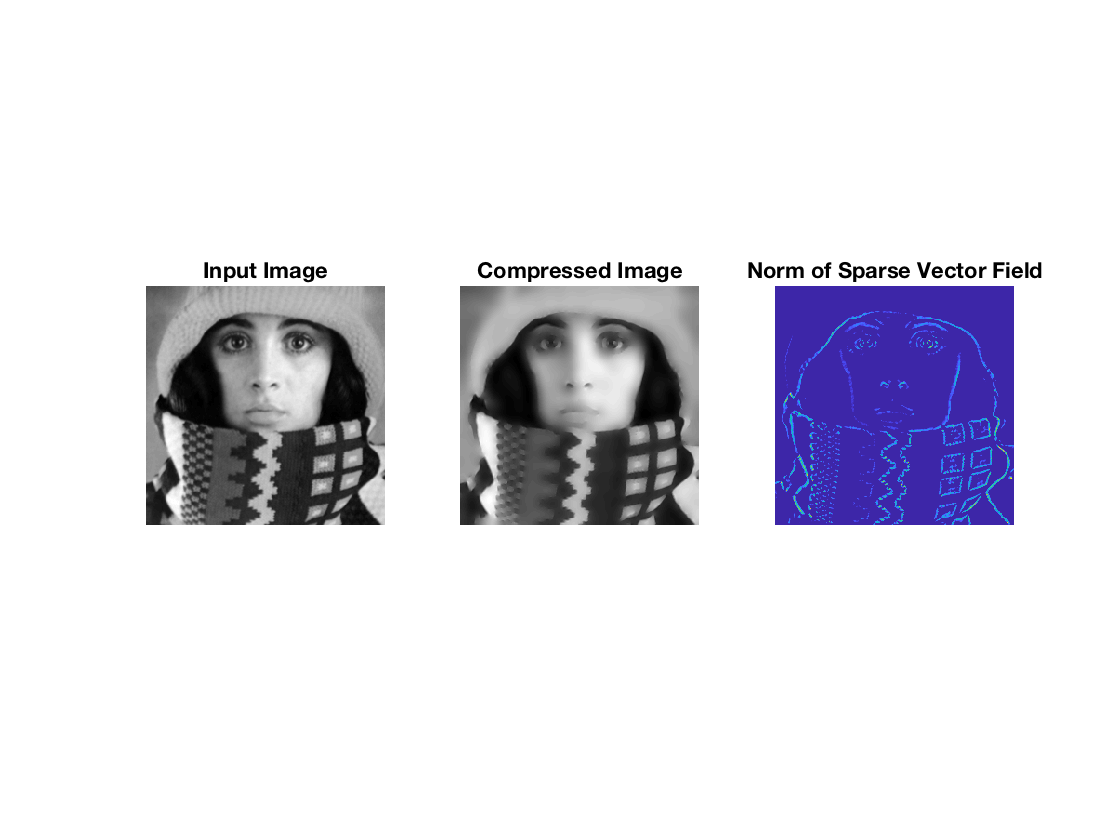

norm_v = sqrt(v(:,:,1).^2 + v(:,:,2).^2);

figure;
subplot(131);imagesc(img);title('Input Image');axis off;axis image;colormap(gca,'gray');
subplot(132);imagesc(u);title('Compressed Image');axis off;axis image;colormap(gca,'gray');
subplot(133);imagesc(norm_v);title('Norm of Sparse Vector Field');axis off;axis image;colormap(gca,'parula');